opts = delimitedTextImportOptions("NumVariables", 17);

% Specify range and delimiter
opts.DataLines = [1, Inf];
opts.Delimiter = ",";            

% Specify column names and types
opts.VariableNames = ["Gender", "Age", "Height", "Weight", "family_history_with_overweight", "FAVC", "FCVC", "NCP", "CAEC", "SMOKE", "CH2O", "SCC", "FAF", "TUE", "CALC", "MTRANS", "NObeyesdad"];
opts.VariableTypes = ["categorical", "double", "double", "double", "categorical", "categorical", "double", "double", "categorical", "categorical", "double", "categorical", "double", "double", "categorical", "categorical", "categorical"];

% Specify file level properties
opts.ExtraColumnsRule = "ignore";
opts.EmptyLineRule = "read";

% Specify variable properties
opts = setvaropts(opts, ["Gender", "family_history_with_overweight", "FAVC", "CAEC", "SMOKE", "SCC", "CALC", "MTRANS", "NObeyesdad"], "EmptyFieldRule", "auto");

% Import the data
data = readtable("\Users\Lenovo\Downloads\ObesityDataSet_raw_and_data_sinthetic (2)\ObesityDataSet_raw_and_data_sinthetic.csv", opts);




data.Gender = renamecats(data.Gender,"Male","1");
data.Gender = renamecats(data.Gender,"Female","0");
data.FAVC = renamecats(data.FAVC,"no","0");
data.FAVC = renamecats(data.FAVC,"yes","1");
data.CAEC = renamecats(data.CAEC,"no","0");
data.CAEC = renamecats(data.CAEC,"Sometimes","1");
data.CAEC = renamecats(data.CAEC,"Frequently","2");
data.CAEC = renamecats(data.CAEC,"Always","3");
data.SMOKE = renamecats(data.SMOKE,"yes","1");
data.SMOKE = renamecats(data.SMOKE,"no","0");
data.SCC = renamecats(data.SCC,"yes","1");
data.SCC = renamecats(data.SCC,"no","0");
data.CALC = renamecats(data.CALC,"no","0");
data.CALC = renamecats(data.CALC,"Sometimes","1");
data.CALC = renamecats(data.CALC,"Frequently","2");
data.CALC = renamecats(data.CALC,"Always","3");
data.MTRANS = renamecats(data.MTRANS,"Walking","0");
data.MTRANS = renamecats(data.MTRANS,"Public_Transportation","1");
data.MTRANS = renamecats(data.MTRANS,"Motorbike","2");
data.MTRANS = renamecats(data.MTRANS,"Bike","3");
data.MTRANS = renamecats(data.MTRANS,"Automobile","4");
data.NObeyesdad = renamecats(data.NObeyesdad,"Insufficient_Weight","1");
data.NObeyesdad = renamecats(data.NObeyesdad,"Normal_Weight","2");
data.NObeyesdad = renamecats(data.NObeyesdad,"Obesity_Type_I","3");
data.NObeyesdad = renamecats(data.NObeyesdad,"Obesity_Type_II","4");
data.NObeyesdad = renamecats(data.NObeyesdad,"Obesity_Type_III","5");
data.NObeyesdad = renamecats(data.NObeyesdad,"Overweight_Level_I","6");
data.NObeyesdad = renamecats(data.NObeyesdad,"Overweight_Level_II","7");
data.family_history_with_overweight = renamecats(data.family_history_with_overweight,"yes","1");
data.family_history_with_overweight = renamecats(data.family_history_with_overweight,"no","0");

%%data visualization and applying KNN

Data=data(2:end,:)

Data = 2111×17 table
    Gender    Age    Height    Weight    family_history_with_overweight    FAVC    FCVC    NCP    CAEC    SMOKE    CH2O    SCC    FAF    TUE    CALC    MTRANS    NObeyesdad
    ______    ___    ______    ______    ______________________________    ____    ____    ___    ____    _____    ____    ___    ___    ___    ____    ______    __________

      0       21      1.62        64                  

DATA=data(2:end,1:16)

DATA = 2111×16 table
    Gender    Age    Height    Weight    family_history_with_overweight    FAVC    FCVC    NCP    CAEC    SMOKE    CH2O    SCC    FAF    TUE    CALC    MTRANS
    ______    ___    ______    ______    ______________________________    ____    ____    ___    ____    _____    ____    ___    ___    ___    ____    ______

      0       21      1.62        64                   1                    0       2       3      1        0       

target=data(2:end,17)

target = 2111×1 table
    NObeyesdad
    __________

        2     
        2     
        2     
        6     
        7     
        2     
        2     
        2     
        2     
        2     
        3     
        7     
        2     
        3     
        2     
        2     



inputTable = Data;
%inputTable = trainingData;


predictorNames = {'Gender', 'Age', 'Height', 'Weight', 'family_history_with_overweight', 'FAVC', 'FCVC', 'NCP', 'CAEC', 'SMOKE', 'CH2O', 'SCC', 'FAF', 'TUE', 'CALC', 'MTRANS'};
predictors = inputTable(:, predictorNames);
response = inputTable.NObeyesdad;
isCategoricalPredictor = [true, false, false, false, true, true, false, false, true, true, false, true, false, false, true, true];

% Train a classifier
% This code specifies all the classifier options and trains the classifier.
template = templateSVM(...
    'KernelFunction', 'gaussian', ...
    'PolynomialOrder', [], ...
    'KernelScale', 1, ...
    'BoxConstraint', 1, ...
    'Standardize', true);
classificationSVM = fitcecoc(...
    predictors, ...
    response, ...
    'Learners', template, ...
    'Coding', 'onevsone', ...
    'ClassNames', categorical({'1'; '2'; '3'; '4'; '5'; '6'; '7'}));

% Create the result struct with predict function
predictorExtractionFcn = @(t) t(:, predictorNames);
svmPredictFcn = @(x) predict(classificationSVM, x);
trainedClassifier.predictFcn = @(x) svmPredictFcn(predictorExtractionFcn(x));

% Add additional fields to the result struct
trainedClassifier.RequiredVariables = {'Age', 'CAEC', 'CALC', 'CH2O', 'FAF', 'FAVC', 'FCVC', 'Gender', 'Height', 'MTRANS', 'NCP', 'SCC', 'SMOKE', 'TUE', 'Weight', 'family_history_with_overweight'};
trainedClassifier.ClassificationSVM = classificationSVM;
trainedClassifier.About = 'This struct is a trained model exported from Classification Learner R2022b.';
trainedClassifier.HowToPredict = sprintf('To make predictions on a new table, T, use: \n  yfit = c.predictFcn(T) \nreplacing ''c'' with the name of the variable that is this struct, e.g. ''trainedModel''. \n \nThe table, T, must contain the variables returned by: \n  c.RequiredVariables \nVariable formats (e.g. matrix/vector, datatype) must match the original training data. \nAdditional variables are ignored. \n \nFor more information, see How to predict using an exported model.');

% Extract predictors and response
% This code processes the data into the right shape for training the
% model.
inputTable =data;
predictorNames = {'Gender', 'Age', 'Height', 'Weight', 'family_history_with_overweight', 'FAVC', 'FCVC', 'NCP', 'CAEC', 'SMOKE', 'CH2O', 'SCC', 'FAF', 'TUE', 'CALC', 'MTRANS'};
predictors = inputTable(:, predictorNames);
response = inputTable.NObeyesdad;
isCategoricalPredictor = [true, false, false, false, true, true, false, false, true, true, false, true, false, false, true, true];

% Perform cross-validation
partitionedModel = crossval(trainedClassifier.ClassificationSVM, 'KFold', 5);

% Compute validation predictions
[validationPredictions, validationScores] = kfoldPredict(partitionedModel);

% Compute validation accuracy
validationAccuracy = 1 - kfoldLoss(partitionedModel, 'LossFun', 'ClassifError');
v1=sprintf('the accuracy of knn is %d',validationAccuracy*100);
disp(v1)

the accuracy of knn is 7.981999e+01



%%% Applying neural networks
t=table2array(target)';
t=double(t);
t = full(ind2vec(t))

t =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     1     1     1     0     0     1     1     1     1     1     0     0     1     0     1     1     0     0     0     0     0     0     1     0     1     1     1     1     1     1     0     0     1     0     1     0     1     1     1     0     0     1     1     1     1     0     1     1     1     1
     0     0     0     0     0     0     0     0     0     0     1     0     0     1     0   

%x=table2array(DATA)
%x=double(x)
data1=[];
for i=1:16
  v =table2array(DATA(:,i));
  v=double(v);
  data1=[data1 v];
  
end
x=data1'

x =     1.0000    1.0000    3.0000    3.0000    3.0000    3.0000    1.0000    3.0000    3.0000    3.0000    3.0000    1.0000    3.0000    3.0000    3.0000    1.0000    3.0000    1.0000    1.0000    1.0000    3.0000    1.0000    1.0000    1.0000    3.0000    3.0000    3.0000    1.0000    3.0000    3.0000    3.0000    1.0000    1.0000    3.0000    3.0000    1.0000    1.0000    1.0000    3.0000    1.0000    1.0000    3.0000    1.0000    3.0000    3.0000    1.0000    3.0000    3.0000    1.0000    1.0000
   21.0000   21.0000   23.0000   27.0000   22.0000   29.0000   23.0000   22.0000   24.0000   22.0000   26.0000   21.0000   22.0000   41.0000   23.0000   22.0000   27.0000   29.0000   30.0000   23.0000   22.0000   52.0000   22.0000   22.0000   21.0000   20.0000   21.0000   23.0000   19.0000   23.0000   29.0000   31.0000   24.0000   39.0000   22.0000   21.0000   22.0000   21.0000   23.0000   21.0000   21.0000   23.0000   21.0000   21.0000   21.0000   21.0000   21.0000   21.0000   20.0000   21

% Choose a Training Function
% For a list of all training functions type: help nntrain
% 'trainlm' is usually fastest.
% 'trainbr' takes longer but may be better for challenging problems.
% 'trainscg' uses less memory. Suitable in low memory situations.
trainFcn = 'trainscg';  % Scaled conjugate gradient backpropagation.

% Create a Pattern Recognition Network
hiddenLayerSize = 100;
net = patternnet(hiddenLayerSize, trainFcn);

% Setup Division of Data for Training, Validation, Testing
net.divideParam.trainRatio = 80/100;
net.divideParam.valRatio = 10/100;
net.divideParam.testRatio = 10/100;

% Train the Network
[net,tr] = train(net,x,t);

% Test the Network
y = net(x);
e = gsubtract(t,y);
performance = perform(net,t,y)

performance = 0.0085

tind = vec2ind(t);
yind = vec2ind(y);
percentErrors = sum(tind ~= yind)/numel(tind);
accuracy = (1-percentErrors)*100;
v=sprintf('the accuracy of NN is %d',accuracy);
disp(v)

the accuracy of NN is 9.810516e+01


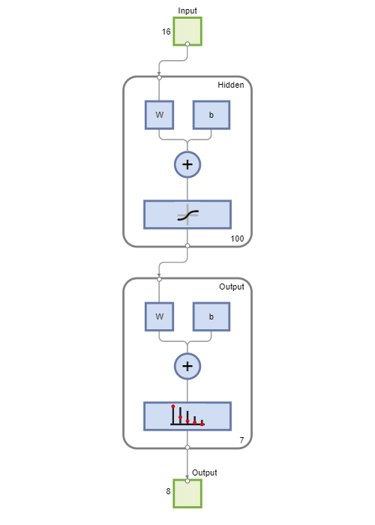

% View the Network
view(net)

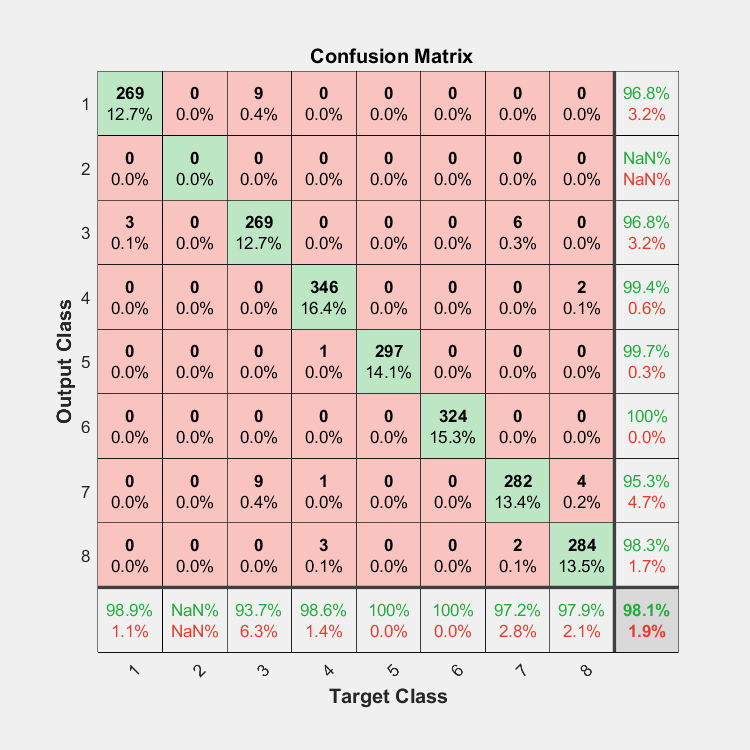


% Plots
% Uncomment these lines to enable various plots.
%figure, plotperform(tr)
%figure, plottrainstate(tr)
%figure, ploterrhist(e)
figure, plotconfusion(t,y)

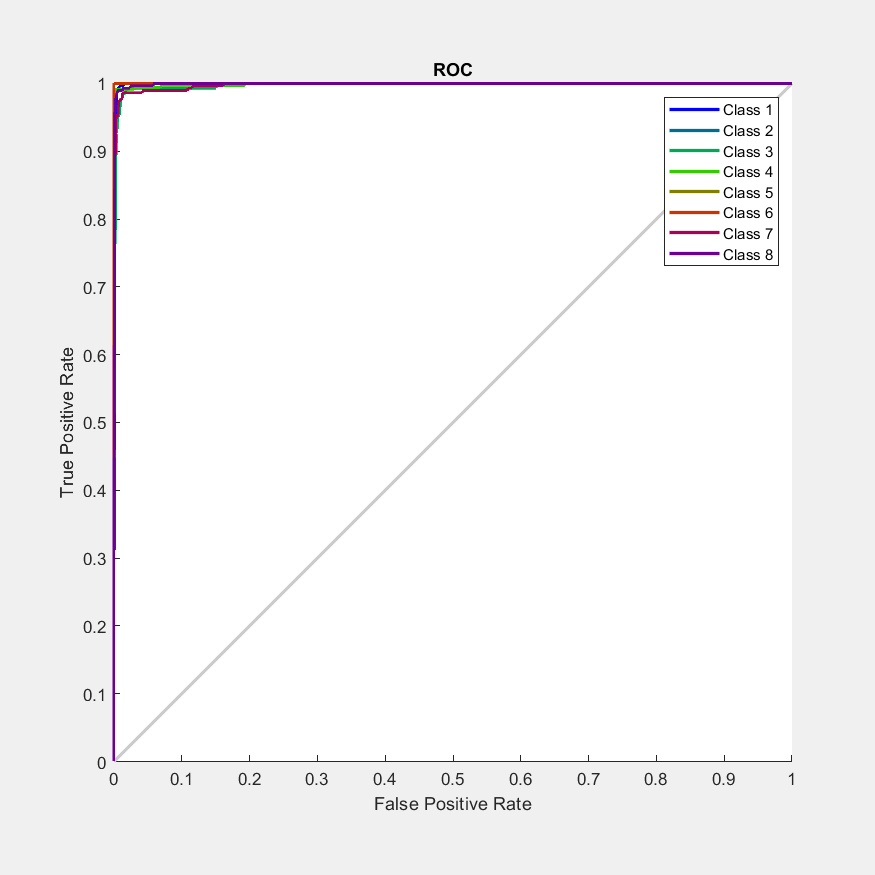

figure, plotroc(t,y)


%%feature selection
inputTable = Data;
predictorNames = {'Gender', 'Age', 'Height', 'Weight', 'family_history_with_overweight', 'FAVC', 'FCVC', 'NCP', 'CAEC', 'SMOKE', 'CH2O', 'SCC', 'FAF', 'TUE', 'CALC', 'MTRANS'};
predictors = inputTable(:, predictorNames);
response =inputTable.NObeyesdad;
isCategoricalPredictor = [true, false, false, false, true, true, false, false, true, true, false, true, false, false, true, true];

% Perform cross-validation
KFolds = 5;
cvp = cvpartition(response, 'KFold', KFolds);
% Initialize the predictions to the proper sizes
validationPredictions = response;
numObservations = size(predictors, 1);
numClasses = 7;
validationScores = NaN(numObservations, numClasses);
for fold = 1:KFolds
    trainingPredictors = predictors(cvp.training(fold),:);
    trainingResponse = response(cvp.training(fold), :);
    foldIsCategoricalPredictor = isCategoricalPredictor;

    % Feature Ranking and Selection
    % Replace Inf/-Inf values with NaN to prepare data for normalization
    trainingPredictors = standardizeMissing(trainingPredictors, {Inf, -Inf});
    % Normalize data for feature ranking
    predictorMatrix = normalize(trainingPredictors, "DataVariable", ~foldIsCategoricalPredictor);
    newPredictorMatrix = zeros(size(predictorMatrix));
    for i = 1:size(predictorMatrix, 2)
        if foldIsCategoricalPredictor(i)
            newPredictorMatrix(:,i) = grp2idx(predictorMatrix{:,i});
        else
            newPredictorMatrix(:,i) = predictorMatrix{:,i};
        end
    end
    predictorMatrix = newPredictorMatrix;
    responseVector = grp2idx(trainingResponse);
end
    % Rank features using ANOVA algorithm
    for i = 1:size(predictorMatrix, 2)
        pValues(i) = anova1(...
            predictorMatrix(:,i), ...
            responseVector, ...
            'off');
    end
    [~,featureIndex] = sort(-log(pValues), 'descend');
    numFeaturesToKeep = 10;
    includedPredictorNames = trainingPredictors.Properties.VariableNames(featureIndex(1:numFeaturesToKeep));
    trainingPredictors = trainingPredictors(:,includedPredictorNames)

trainingPredictors = 1689×10 table
    Weight    Gender    family_history_with_overweight    FCVC    Age    CAEC    FAVC    Height    CALC    MTRANS
    ______    ______    ______________________________    ____    ___    ____    ____    ______    ____    ______

       64       0                     1                    2      21      1       0       1.62      0        1   
       56       0                     1                    3      21      1       0       1.52      1        1   
       77       1                     1                    2      23      1       0        1.8      2        1   
       87       1                     0               

    foldIsCategoricalPredictor = foldIsCategoricalPredictor(featureIndex(1:numFeaturesToKeep));
    t1=trainingResponse;
    t1=double(t1);
    t1 = full(ind2vec(t1'))

t1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     1     1     1     0     0     1     1     1     1     0     0     1     0     1     0     0     0     0     0     0     1     0     1     1     1     1     1     1     0     0     1     1     0     1     1     0     0     1     1     1     1     0     1     1     1     1     1     1     1     1
     0     0     0     0     0     0     0     0     0     1     0     0     1     0     0  

%x=table2array(DATA)
%x=double(x)
data2=[];
for i=1:10
  v =table2array(trainingPredictors(:,i));
  v=double(v);
  data2=[data2 v];
  
end
x1=data2'

x1 =    64.0000   56.0000   77.0000   87.0000   89.8000   53.0000   53.0000   64.0000   68.0000  105.0000   80.0000   56.0000   99.0000   60.0000  102.0000   78.0000   82.0000   70.0000   80.0000   87.0000   60.0000   82.0000   68.0000   50.0000   65.0000   52.0000   76.0000   70.0000   83.0000   68.0000   76.0000   62.0000   65.0000   49.0000   67.0000   88.0000   75.0000   60.0000   64.0000   62.0000   80.0000   65.0000   72.0000   72.0000   60.0000   50.0000   44.0000   52.0000   55.0000   55.0000
    1.0000    1.0000    3.0000    3.0000    3.0000    3.0000    3.0000    3.0000    3.0000    3.0000    1.0000    3.0000    3.0000    3.0000    3.0000    1.0000    1.0000    1.0000    3.0000    1.0000    1.0000    1.0000    3.0000    3.0000    3.0000    1.0000    3.0000    3.0000    3.0000    1.0000    1.0000    3.0000    1.0000    1.0000    3.0000    1.0000    1.0000    3.0000    1.0000    3.0000    3.0000    1.0000    3.0000    3.0000    1.0000    1.0000    1.0000    1.0000    1.0000    

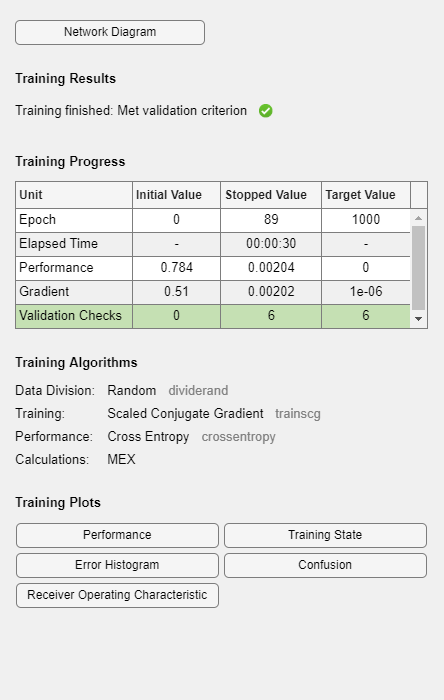

trainFcn = 'trainscg';  % Scaled conjugate gradient backpropagation.

% Create a Pattern Recognition Network
hiddenLayerSize = 100;
net = patternnet(hiddenLayerSize, trainFcn);

% Setup Division of Data for Training, Validation, Testing
net.divideParam.trainRatio = 80/100;
net.divideParam.valRatio = 10/100;
net.divideParam.testRatio = 10/100;

% Train the Network
[net,tr] = train(net,x1,t1);


% Test the Network
y = net(x1);
e = gsubtract(t1,y);
performance = perform(net,t1,y)

performance = 0.0068

tind = vec2ind(t1);
yind = vec2ind(y);
percentErrors = sum(tind ~= yind)/numel(tind);
accuracy = (1-percentErrors)*100;
v=sprintf('the accuracy of NN is %d',accuracy);
disp(v)

the accuracy of NN is 9.875666e+01


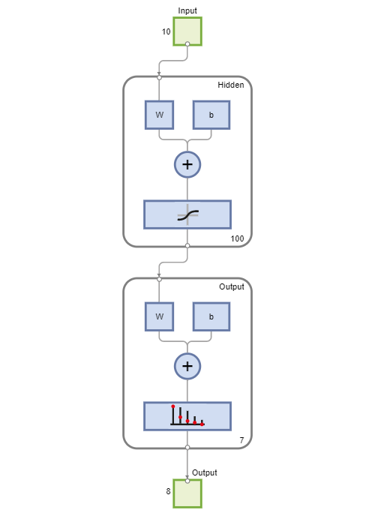

% View the Network
view(net)

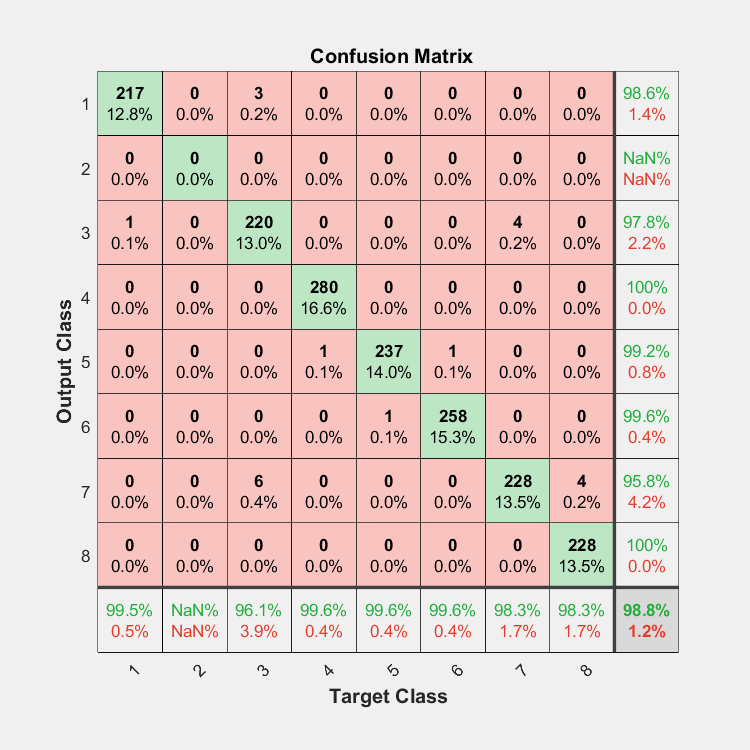


% Plots
% Uncomment these lines to enable various plots.
%figure, plotperform(tr)
%figure, plottrainstate(tr)
%figure, ploterrhist(e)
figure, plotconfusion(t1,y)

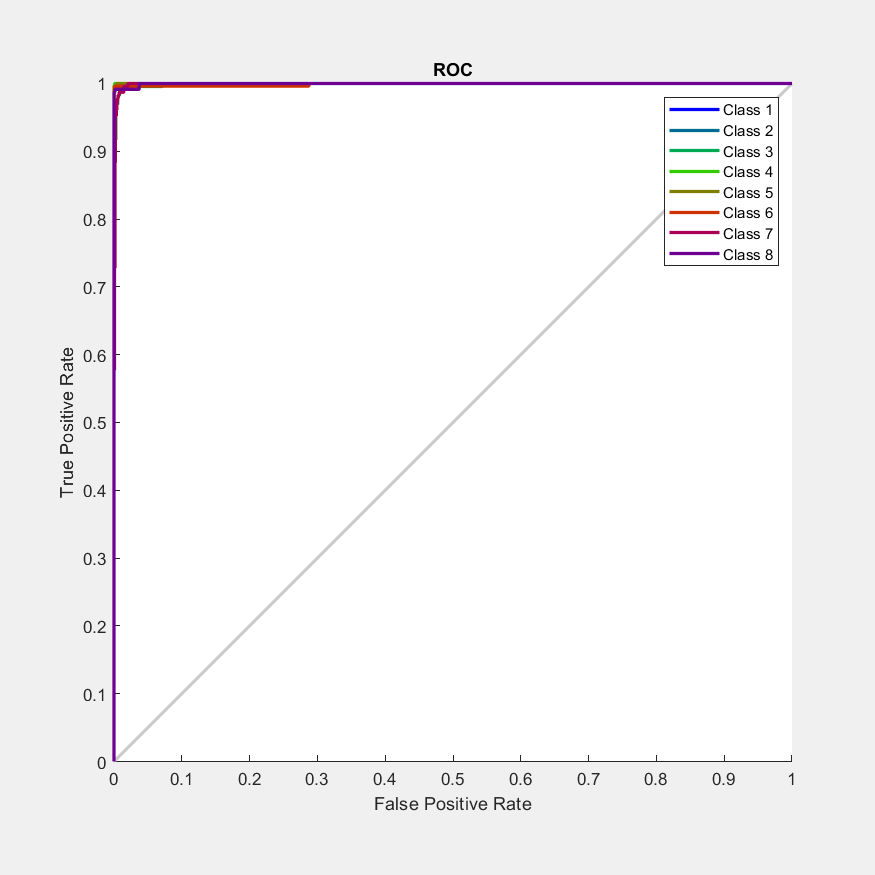

figure, plotroc(t1,y)